# ImageLab — Image Enhancement using Spatial Domain Filters

**An Interactive MATLAB-Based Image Processing and Learning Laboratory**

This Live Script demonstrates the core of the ImageLab project directly in MATLAB: noise models, linear and non-linear spatial filters (toolbox AND manual implementations), correlation vs convolution, histogram processing, sharpening, edge detection and segmentation. Every function used here lives in the project folders (algorithms/, noise/, histogram/, metrics/ ...).

Scope: spatial-domain processing only (no frequency-domain filtering).

ilab_setup;                      % add all ImageLab folders to the path
fprintf('Image Processing Toolbox available: %d\n', hasIPT());

Image Processing Toolbox available: 0


## 1. Digital image fundamentals

A digital image is a matrix of sampled and quantised intensities. An RGB image is an M x N x 3 array; `toGray` combines the channels with the luminance weights 0.2989, 0.5870, 0.1140 (the same as `rgb2gray`).

I = toDouble(imread('peppers.png'));
G = toGray(I);
fprintf('Size: %d x %d x %d, class after conversion: %s\n', size(I,1), size(I,2), size(I,3), class(I));

Size: 384 x 512 x 3, class after conversion: double


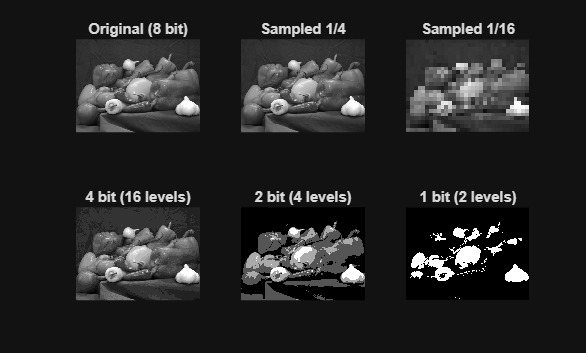


figure('Name', 'Sampling and quantisation');
subplot(2,3,1), imshow(G), title('Original (8 bit)')
subplot(2,3,2), imshow(sampleImage(G, 4)), title('Sampled 1/4')
subplot(2,3,3), imshow(sampleImage(G, 16)), title('Sampled 1/16')
subplot(2,3,4), imshow(quantizeImage(G, 4)), title('4 bit (16 levels)')
subplot(2,3,5), imshow(quantizeImage(G, 2)), title('2 bit (4 levels)')
subplot(2,3,6), imshow(quantizeImage(G, 1)), title('1 bit (2 levels)')

## 2. Noise models (image degradation)

Degradation model: g = h * f + eta. Here h is the identity and eta is noise.

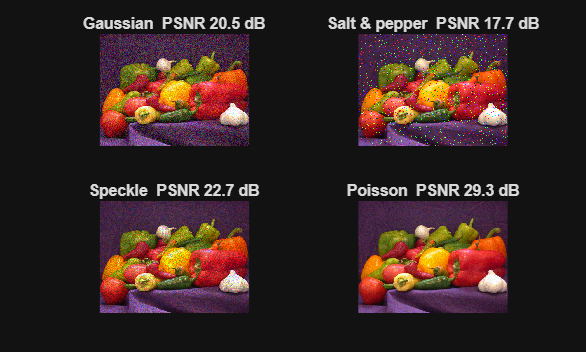

rng(1);
Ngauss = addGaussianNoise(I, 0, 0.01);
Nsp    = addSaltPepperNoise(I, 0.05);
Nspk   = addSpeckleNoise(I, 0.04);
Npois  = addPoissonNoise(I);

figure('Name', 'Noise models');
subplot(2,2,1), imshow(Ngauss), title(sprintf('Gaussian  PSNR %.1f dB', calculatePSNR(Ngauss, I)))
subplot(2,2,2), imshow(Nsp),    title(sprintf('Salt & pepper  PSNR %.1f dB', calculatePSNR(Nsp, I)))
subplot(2,2,3), imshow(Nspk),   title(sprintf('Speckle  PSNR %.1f dB', calculatePSNR(Nspk, I)))
subplot(2,2,4), imshow(Npois),  title(sprintf('Poisson  PSNR %.1f dB', calculatePSNR(Npois, I)))

## 3. Mean filter — toolbox vs manual implementation

The mean filter replaces each pixel by the average of its k x k neighbourhood. `meanFilter` uses fspecial + imfilter (or conv2 without the toolbox); `meanFilterManual` uses two nested loops. The results are identical.

tic; Jt = meanFilter(G, 3);       tToolbox = toc;
tic; Jm = meanFilterManual(G, 3); tManual  = toc;
fprintf('Max difference toolbox vs manual: %g\n', max(abs(Jt(:) - Jm(:))));

Max difference toolbox vs manual: 4.44089e-16


fprintf('Time: toolbox %.1f ms, manual loops %.1f ms\n', 1000*tToolbox, 1000*tManual);

Time: toolbox 435.4 ms, manual loops 2100.3 ms


## 4. Median filter and salt-and-pepper noise

The median filter sorts the neighbourhood and selects the middle value. Impulses (0 or 1) end up at the ends of the sorted list and are ignored, so they are removed completely while edges stay sharp. The mean filter only smears them.

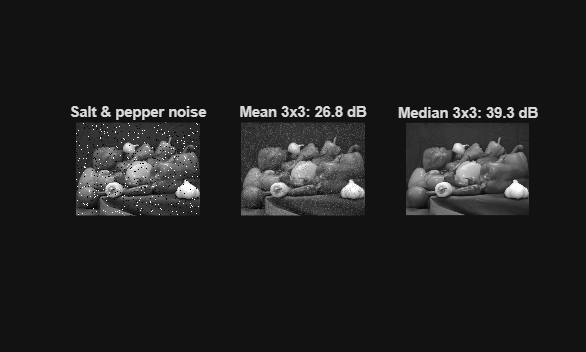

Gsp = addSaltPepperNoise(G, 0.05);
Jmean   = meanFilter(Gsp, 3);
Jmedian = medianFilterManual(Gsp, 3);       % manual: extract, sort, pick middle

figure('Name', 'Mean vs median on salt & pepper noise');
subplot(1,3,1), imshow(Gsp),     title('Salt & pepper noise')
subplot(1,3,2), imshow(Jmean),   title(sprintf('Mean 3x3: %.1f dB', calculatePSNR(Jmean, G)))
subplot(1,3,3), imshow(Jmedian), title(sprintf('Median 3x3: %.1f dB', calculatePSNR(Jmedian, G)))

## 5. Order-statistic filters: min, median, max

`ordfilt2(I, rank, true(3))` — rank 1 = minimum, 5 = median, 9 = maximum.

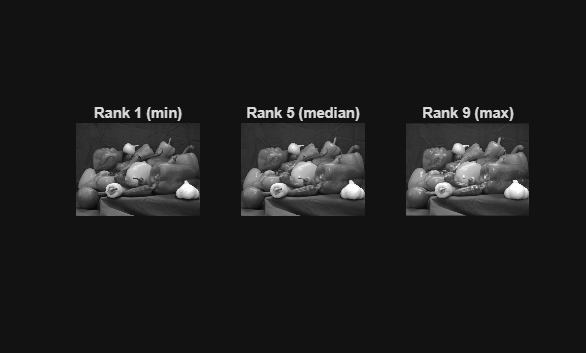

figure('Name', 'Order statistics');
subplot(1,3,1), imshow(orderStatisticFilter(G, 3, 1)), title('Rank 1 (min)')
subplot(1,3,2), imshow(orderStatisticFilter(G, 3, 5)), title('Rank 5 (median)')
subplot(1,3,3), imshow(orderStatisticFilter(G, 3, 9)), title('Rank 9 (max)')

## 6. Gaussian filter and the manually built kernel

G(x,y) = exp(-(x^2+y^2)/(2 sigma^2)), normalised to sum 1.

K = gaussianKernel(5, 1)

K =     0.0030    0.0133    0.0219    0.0133    0.0030
    0.0133    0.0596    0.0983    0.0596    0.0133
    0.0219    0.0983    0.1621    0.0983    0.0219
    0.0133    0.0596    0.0983    0.0596    0.0133
    0.0030    0.0133    0.0219    0.0133    0.0030


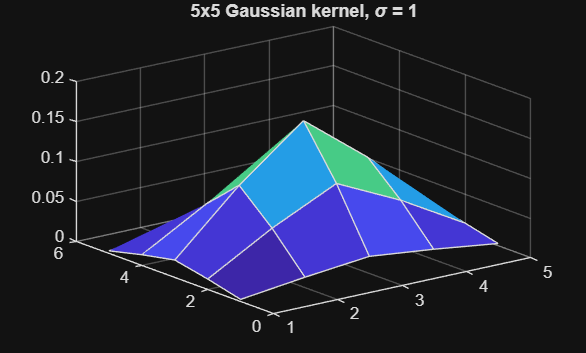

figure('Name', 'Gaussian kernel'); surf(K), title('5x5 Gaussian kernel, \sigma = 1')

## 7. Comparing filters on the same noisy image

The PSNR of each filter is compared with a bar chart, as in the Filter Comparison lab.

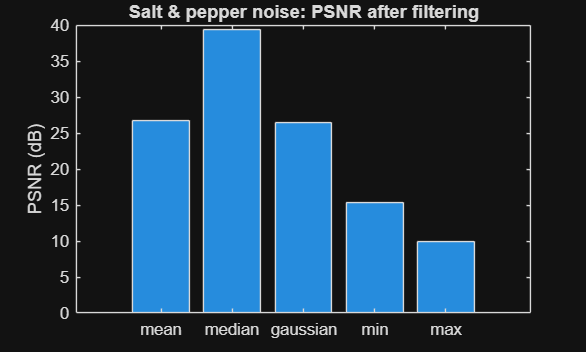

names = {'mean', 'median', 'gaussian', 'min', 'max'};
psnrValues = zeros(1, numel(names));
for k = 1:numel(names)
    J = ilab_runFilter(Gsp, names{k}, 3, struct('sigma', 1), 'toolbox');
    psnrValues(k) = calculatePSNR(J, G);
end
figure('Name', 'Filter comparison');
bar(psnrValues), xticklabels(names), ylabel('PSNR (dB)'), title('Salt & pepper noise: PSNR after filtering')

## 8. Correlation vs convolution

Correlation slides the kernel as it is; convolution rotates it by 180 degrees first. The manual results match filter2 and conv2.

A  = [1 2 3; 4 5 6; 7 8 9];
Kc = [1 0 -1; 1 0 -1; 1 0 -1];
[C, steps] = manualCorrelation(A, Kc, 'same');
C

C =     -7    -4     7
   -15    -6    15
   -13    -4    13


centreStep = steps(5)                    % window, products and sum at the centre

centreStep = struct with fields:
         row: 2
         col: 2
      window: [3×3 double]
    products: [3×3 double]
         sum: -6


[V, ~, flipped] = manualConvolution(A, Kc, 'same');
flipped

flipped =     -1     0     1
    -1     0     1
    -1     0     1


V

V =      7     4    -7
    15     6   -15
    13     4   -13


isequal(C, filter2(Kc, A, 'same')) && isequal(V, conv2(A, Kc, 'same'))

ans = logical
   1


## 9. Histogram processing

Equalisation maps each level through the scaled CDF: s_k = (L-1) sum p(r_j).

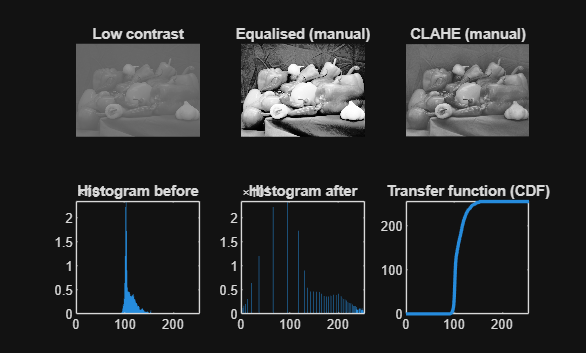

low = 0.35 + 0.25 * G;                    % a low-contrast image
[E, mapping] = histogramEqualizationManual(low);
figure('Name', 'Histogram equalisation');
subplot(2,3,1), imshow(low), title('Low contrast')
subplot(2,3,2), imshow(E), title('Equalised (manual)')
subplot(2,3,3), imshow(claheManual(low, [8 8], 0.01)), title('CLAHE (manual)')
subplot(2,3,4), bar(imhistManual(low), 1), xlim([0 255]), title('Histogram before')
subplot(2,3,5), bar(imhistManual(E), 1), xlim([0 255]), title('Histogram after')
subplot(2,3,6), plot(0:255, mapping, 'LineWidth', 2), axis([0 255 0 255]), title('Transfer function (CDF)')

s1 = imageStatistics(low); s2 = imageStatistics(E);
fprintf('Std: %.1f -> %.1f    Entropy: %.2f -> %.2f bits\n', s1.std, s2.std, s1.entropy, s2.entropy);

Std: 11.6 -> 70.1    Entropy: 5.01 -> 4.97 bits


## 10. Sharpening

Laplacian sharpening g = f - lap(f) and unsharp masking g = f + k (f - blur(f)).

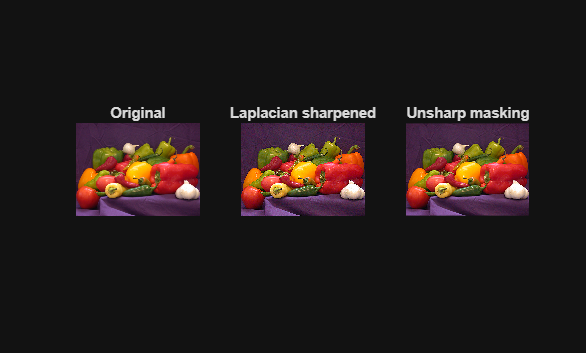

[S, L] = laplacianSharpen(I, 0.2, 1);
U = unsharpMask(I, 1.5, 1);
figure('Name', 'Sharpening');
subplot(1,3,1), imshow(I), title('Original')
subplot(1,3,2), imshow(S), title('Laplacian sharpened')
subplot(1,3,3), imshow(U), title('Unsharp masking')

## 11. Edge detection

First-derivative operators (Roberts, Prewitt, Sobel) and Canny.

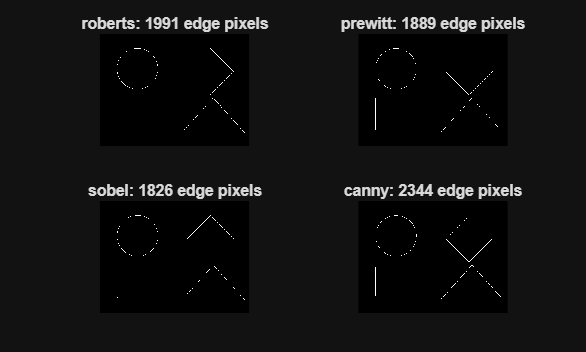

shapes = toDouble(imread(fullfile(fileparts(which('ilab_setup')), 'sample_images', 'shapes.png')));
methods = {'roberts', 'prewitt', 'sobel', 'canny'};
figure('Name', 'Edge detection');
for k = 1:numel(methods)
    BW = edgeDetect(shapes, methods{k});
    subplot(2,2,k), imshow(BW), title(sprintf('%s: %d edge pixels', methods{k}, nnz(BW)))
end

## 12. Segmentation

Otsu's threshold maximises the between-class variance; adaptive thresholding handles uneven illumination.

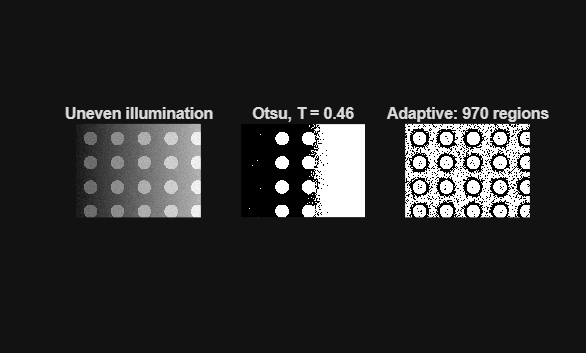

U = toDouble(imread(fullfile(fileparts(which('ilab_setup')), 'sample_images', 'unevenlight.png')));
[B1, T] = otsuThreshold(U);
B2 = adaptiveThreshold(U, 31, 0.02);
[Lbl, n] = labelComponents(B2, 8);
figure('Name', 'Thresholding');
subplot(1,3,1), imshow(U), title('Uneven illumination')
subplot(1,3,2), imshow(B1), title(sprintf('Otsu, T = %.2f', T))
subplot(1,3,3), imshow(B2), title(sprintf('Adaptive: %d regions', n))

## 13. Colour enhancement

Equalising the V channel of HSV improves contrast without shifting hues.

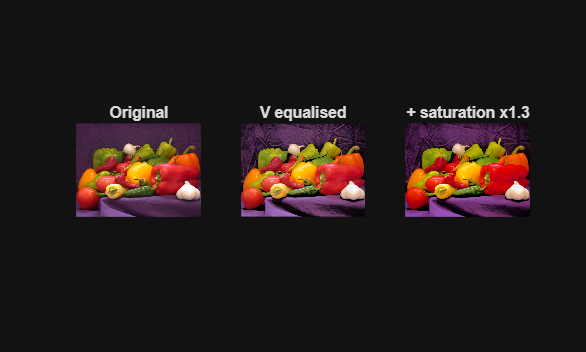

J1 = colorEnhance(I, 'hsv', 3, 'equalize');
J2 = colorEnhance(J1, 'hsv', 2, 'gain', 1.3);
figure('Name', 'Colour enhancement');
subplot(1,3,1), imshow(I), title('Original')
subplot(1,3,2), imshow(J1), title('V equalised')
subplot(1,3,3), imshow(J2), title('+ saturation x1.3')

## Observations

- The manual (loop) implementations give exactly the same results as the toolbox / vectorised versions; they are slower but show each step.

- The median filter clearly outperforms the mean filter on salt & pepper noise; averaging filters are better for Gaussian noise.

- Convolution equals correlation with a 180-degree rotated kernel.

- Histogram equalisation increases the standard deviation (contrast).

- Sharpening enhances edges but also amplifies noise.

- Canny gives thin, connected edges; adaptive thresholding handles uneven light.

## Conclusion

Spatial-domain filters are simple, local and powerful. Linear filters (mean, Gaussian) suit Gaussian noise; non-linear order-statistic filters (median) suit impulse noise; derivative filters sharpen and detect edges; histogram processing enhances contrast. ImageLab implements each algorithm both with the MATLAB Image Processing Toolbox and manually, demonstrating an understanding of how each operation works.